# Transfer function Model:

## Modelling the System:

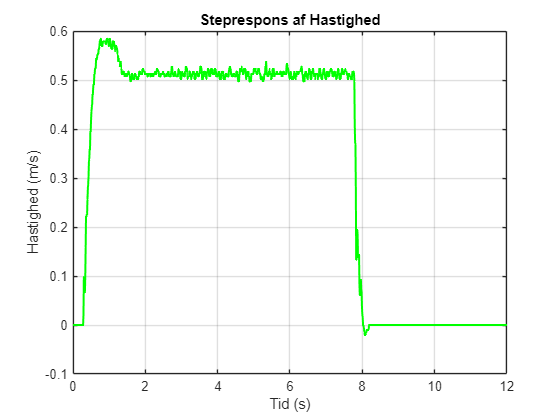

clc; clear; close all;
% Load the data
data = readmatrix('training_data');  
validation_data = readmatrix('test_data');  

% Extract columns
x_position = data(:, 1);  % $odox$ (x-coordinate of position)
velocity = data(:, 2);  % $odovelocity$ (velocity)
time = data(:, 3) - data(1, 3); % Time in seconds
T = mean(diff(time));  % Compute the average sampling time

% Plot raw velocity data 
figure;
plot(time, velocity, 'g', 'LineWidth', 1.5); % Measured Velocity (Green)
title('Steprespons af Hastighed');
xlabel('Tid (s)');
ylabel('Hastighed (m/s)');
grid on;


% ---- Find t_start Dynamically ----
first_motion_idx = find(velocity > 0, 1, 'first'); % Find first velocity change
t_start_idx = max(first_motion_idx - 5, 1); % Five indices before motion starts
t_start = time(t_start_idx); % Get corresponding time value
disp(['Start time adjusted to: ', num2str(t_start), ' seconds']);

Start time adjusted to: 0.23981 seconds



% Define the cutoff time
t_end = 5; % Keep only the rising part and steady-state

% Find indices for the selected time range
idx = (time >= t_start) & (time <= t_end);

% Apply trimming
time_trimmed = time(idx) - t_start; % Shift so t=0 at motion start
velocity_trimmed = velocity(idx);

% Step Input with Amplitude 0.5
step_input = 0.5 * ones(size(time_trimmed));

% Transfer function estimation (2nd order model)
data_id = iddata(velocity_trimmed, step_input, T); 
sys_tf = tfest(data_id, 2, 0); % 2nd order system

disp(sys_tf);

  idtf with properties:

        Numerator: 21.102609785439693
      Denominator: [1 5.704630203235490 20.579469586677028]
         Variable: 's'
          IODelay: 0
        Structure: [1×1 pmodel.tf]
    NoiseVariance: 9.449386949339315e-07
       InputDelay: 0
      OutputDelay: 0
        InputName: {'u1'}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {'y1'}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]
           Report: [1×1 idresults.tfest]



### Compare

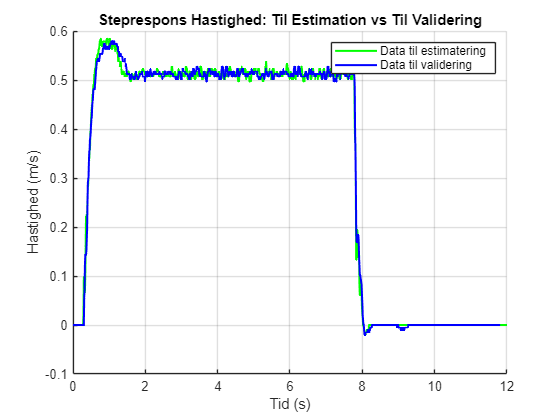

% --- Process test data the same way ---
x_position_test = validation_data(:, 1);
velocity_test = validation_data(:, 2);
time_test = validation_data(:, 3) - validation_data(1, 3);

% Compare raw data:
figure;
hold on;
plot(time, velocity, 'g', 'LineWidth', 1.5); % Training data velocity
plot(time_test, velocity_test, 'b', 'LineWidth', 1.5); % Test data velocity
title('Steprespons Hastighed: Til Estimation vs Til Validering');
xlabel('Tid (s)');
ylabel('Hastighed (m/s)');
legend('Data til estimatering', 'Data til validering');
grid on;
hold off;


% Use same logic to find motion start
first_motion_idx_test = find(velocity_test > 0, 1, 'first');
t_start_idx_test = max(first_motion_idx_test - 5, 1);
t_start_test = time_test(t_start_idx_test);

% Keep the same 5s window after motion
idx_test = (time_test >= t_start_test) & (time_test <= t_start_test + 5);
time_trimmed_test = time_test(idx_test) - t_start_test;
velocity_trimmed_test = velocity_test(idx_test);

% Generate step input (same as before)
step_input_test = 0.5 * ones(size(time_trimmed_test));

% Create iddata for test data
data_id_test = iddata(velocity_trimmed_test, step_input_test, T);

figure;
compare(sys_tf, data_id_test);
% Overwrite title and labels manually
title('Estimeret Model vs Valideringsdata');
xlabel('Tid (s)');
ylabel('Hastighed (m/s)');
legend('Valideringsdata', 'Estimeret Robot Model');
grid on;




### Step responses plots:

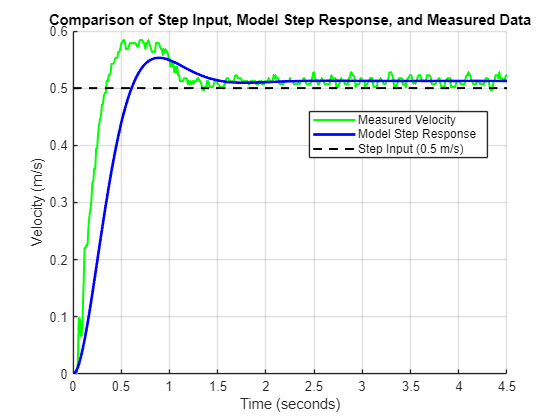

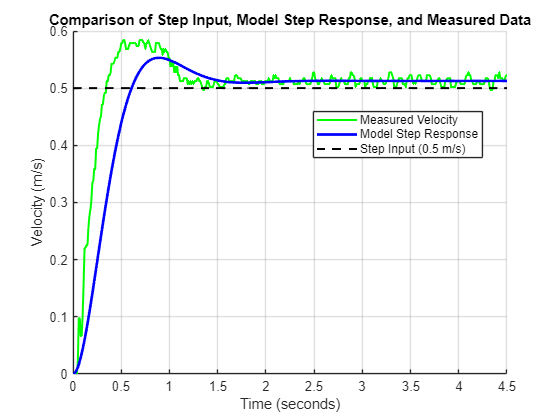


% Generate step response for identified transfer function
t_sim = 0:T:(time_trimmed(end)); % Ensure step response starts at t=0
[step_response, step_time] = step(0.5 * sys_tf, t_sim); 

% Interpolate step response to match measured time vector
step_response_interp = interp1(step_time, step_response, time_trimmed, 'linear', 'extrap');

% Plot everything in one figure
figure;
hold on;
plot(time_trimmed, velocity_trimmed, 'g', 'LineWidth', 1.5); % Measured Velocity (Green)
plot(time_trimmed, step_response_interp, 'b', 'LineWidth', 2); % Model Step Response (Blue)
plot(time_trimmed, step_input, 'k--', 'LineWidth', 1.5); % Step Input (Black Dashed)
title('Comparison of Step Input, Model Step Response, and Measured Data');
xlabel('Time (seconds)');
ylabel('Velocity (m/s)');
xlim([0 4.5])
legend('Measured Velocity', 'Model Step Response', 'Step Input (0.5 m/s)', 'Location', 'Best');
grid on;
hold off;


p = pole(sys_tf);
z = zero(sys_tf);

figure;
plot(real(p), imag(p), 'rx', 'MarkerSize', 10, 'LineWidth', 2); hold on;
plot(real(z), imag(z), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('Re');
ylabel('Im');
title('Pole-Zero Map (Cartesian)');
legend('Poles', 'Zeros');

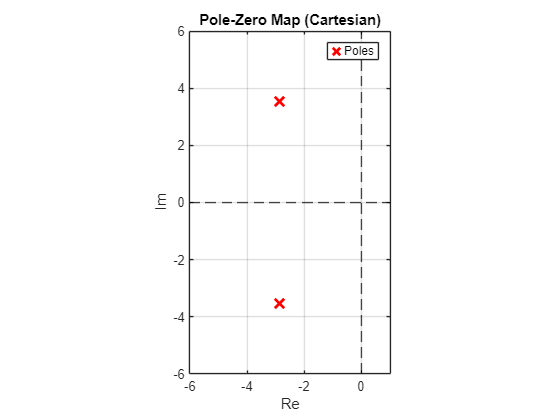

grid on;
axis equal;
xline(0, 'k--', 'HandleVisibility', 'off');
yline(0, 'k--', 'HandleVisibility', 'off');
% Zoom out manually
xlim([-6, 1]);
ylim([-6, 6]);


% Additional analysis
stepinfo(sys_tf) % Step response characteristics

ans = struct with fields:
         RiseTime: 0.424726601503734
    TransientTime: 1.320054341718061
     SettlingTime: 1.320054341718061
      SettlingMin: 0.940242618087413
      SettlingMax: 1.106268288783431
        Overshoot: 7.884355703872026
       Undershoot: 0
             Peak: 1.106268288783431
         PeakTime: 0.887995719987845


sys_tf % Display transfer function


sys_tf =
 
  From input "u1" to output "y1":
          21.1
  ---------------------
  s^2 + 5.705 s + 20.58
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "data_id".
Fit to estimation data: 88.68%                      
FPE: 9.549e-05, MSE: 9.35e-05                       
 
Model Properties


pole(sys_tf)

ans =  -2.852315101617745 + 3.527572557405500i
 -2.852315101617745 - 3.527572557405500i


zero(sys_tf)


ans =

  0×1 empty double column vector




% Frequency response
figure;
bodeplot(sys_tf)
grid on;

## P-Controller Design

Gs = sys_tf;  % Identified system transfer function

% Define controller parameters
gamma_m = 60;  % Desired phase margin in degrees

% Frequency range for analysis
w = logspace(-2, 2, 3000);  
[mag, phase] = bode(Gs, w);

% Compute phase crossover
pc = gamma_m - 180;

% Find the crossover frequency
n = find(phase > pc, 1, 'last');  
wc = w(n);  % Corresponding frequency

% Compute open-loop gain at crossover frequency
[magc, phase] = bode(Gs, wc);
Kp = 1 / magc  % Correct gain to achieve the desired phase margin

Kp =    2.013838737141522



% Closed-loop transfer function
Gol = Gs * Kp


Gol =
 
  From input to output "y1":
          42.5
  ---------------------
  s^2 + 5.705 s + 20.58
 
Continuous-time transfer function.
Model Properties


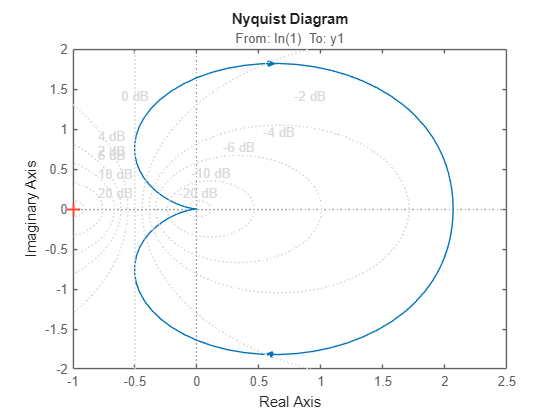

Gcl = Gol  / (1 + Gol);



% Nyquist Plot to verify stability
figure;
nyquist(Gol)
grid on;


pole(Gol) % yes, it is stable

ans =  -2.852315101617745 + 3.527572557405500i
 -2.852315101617745 - 3.527572557405500i


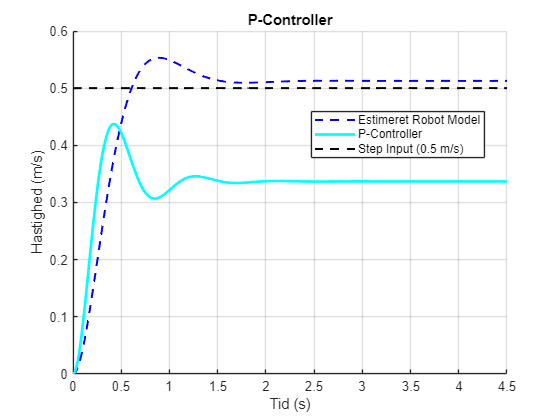


% Bode Plot to verify phase margin
figure();
margin(Gol);
title('Bode Diagram with P Controller');
grid on;

t_sim = 0:T:time_trimmed(end); % Ensure matching time vector

% Simulate step response for each system
[y_Gcl_p, t_Gcl] = step(0.5 *Gcl, t_sim);  % Closed-loop response
[y_sys_tf, t_sys_tf] = step(0.5 * sys_tf, t_sim);  % Modeled system response

% Interpolate the closed-loop response to match measured time
y_Gcl_P = interp1(t_Gcl, y_Gcl_p, time_trimmed, 'linear', 'extrap');
y_sys_tf_interp = interp1(t_sys_tf, y_sys_tf, time_trimmed, 'linear', 'extrap');

% Step Response Comparison
figure();
    hold on;
    
    % Plot all responses in one figure
    plot(time_trimmed, y_sys_tf_interp, 'b--', 'LineWidth', 1.5); % Modeled system response
    plot(time_trimmed, y_Gcl_P, 'c', 'LineWidth', 2); % Closed-loop response
    % Step input (black dashed)
    plot(time_trimmed, step_input, 'k--', 'LineWidth', 1.5);
    % Labels & legend
    title('P-Controller');
    xlabel('Tid (s)');
    ylabel('Hastighed (m/s)');
    legend('Estimeret Robot Model', 'P-Controller','Step Input (0.5 m/s)' , 'Location', 'Best');
    xlim([0 4.5])
    grid on;
    hold off;


Gcl %displays the transfer function


Gcl =
 
  From input "y1" to output "y1":
           42.5 s^2 + 242.4 s + 874.6
  --------------------------------------------
  s^4 + 11.41 s^3 + 116.2 s^2 + 477.2 s + 1298
 
Continuous-time transfer function.
Model Properties


stepinfo(Gcl)

ans = struct with fields:
         RiseTime: 0.177012111942746
    TransientTime: 1.371023947100567
     SettlingTime: 1.371023947100567
      SettlingMin: 0.613820137795487
      SettlingMax: 0.874757177739471
        Overshoot: 29.836193915254626
       Undershoot: 0
             Peak: 0.874757177739471
         PeakTime: 0.419779794903345


ess = 0.5*(1-dcgain(Gcl))

ess =    0.163130460251155



% Kp = 16
% 
% % Closed-loop transfer function
% Gol = Gs * Kp
% Gcl = Gol  / (1 + Gol);
% 
% 
% 
% % Nyquist Plot to verify stability
% figure;
% nyquist(Gol)
% grid on;
% 
% pole(Gol) % yes, it is stable
% 
% % Bode Plot to verify phase margin
% figure();
% margin(Gol);
% title('Bode Diagram with P Controller');
% grid on;
% 
% t_sim = 0:T:time_trimmed(end); % Ensure matching time vector
% 
% % Simulate step response for each system
% [y_Gcl_p, t_Gcl] = step(0.5 *Gcl, t_sim);  % Closed-loop response
% [y_sys_tf, t_sys_tf] = step(0.5 * sys_tf, t_sim);  % Modeled system response
% 
% % Interpolate the closed-loop response to match measured time
% y_Gcl_P = interp1(t_Gcl, y_Gcl_p, time_trimmed, 'linear', 'extrap');
% y_sys_tf_interp = interp1(t_sys_tf, y_sys_tf, time_trimmed, 'linear', 'extrap');
% 
%% Step Response Comparison
% figure();
%     hold on;
% 
%     % Plot all responses in one figure
%     plot(time_trimmed, y_sys_tf_interp, 'b--', 'LineWidth', 1.5); % Modeled system response
%     plot(time_trimmed, y_Gcl_P, 'c', 'LineWidth', 2); % Closed-loop response
%     % Step input (black dashed)
%     plot(time_trimmed, step_input, 'k--', 'LineWidth', 1.5);
%     % Labels & legend
%     title('P-Controller');
%     xlabel('Tid (s)');
%     ylabel('Hastighed (m/s)');
%     legend('Estimeret Robot Model', 'P-Controller','Step Input (0.5 m/s)' , 'Location', 'Best');
%     grid on;
%     xlim([0 4.5])
%     hold off;
% 
% Gcl %displays the transfer function
% stepinfo(Gcl)
% ess = 0.5*(1-dcgain(Gcl) 

## PI-Controller:

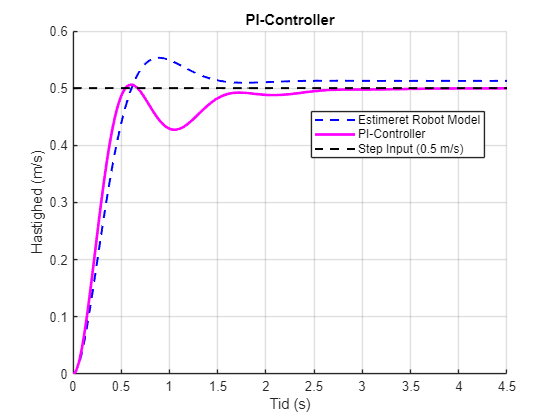

N_i = 2;
gamma_m = 60;  % Desired phase margin in degrees

% Frequency range for analysis
w = logspace(-2, 2, 3000);  
[mag, phase] = bode(Gs, w);
phi_i = rad2deg(atan2(-1, N_i));  % Integral compensator phase
pc = gamma_m - 180 - phi_i;  % Phase crossover

% Find the crossover frequency
n = find(phase > pc, 1, 'last');  
wc = w(n);  % Corresponding frequency

% Compute controller time constants
tau_i = N_i / wc;
Ci = tf([tau_i 1], [tau_i 0]);  % Integral compensator

% Compute open-loop gain at crossover frequency
[magc, phasec] = bode(Gs*Ci, wc);
Kp = 1 / magc;  % Correct gain to achieve the desired phase margin

% Open-loop and closed-loop transfer functions
Gol = Kp * Gs * Ci;
Gcl = Gol / (1 + Gol);

t_sim = 0:T:time_trimmed(end); % Ensure matching time vector

% Simulate step response for each system
[y_Gcl_Pi, t_Gcl] = step(0.5 * Gcl, t_sim);  % Closed-loop response

% Interpolate the closed-loop response to match measured time
y_Gcl_PI = interp1(t_Gcl, y_Gcl_Pi, time_trimmed, 'linear', 'extrap');

% Step Response Comparison
figure();
    hold on;
    
    % Plot all responses in one figure
    plot(time_trimmed, y_sys_tf_interp, 'b--', 'LineWidth', 1.5); % Modeled system response
    plot(time_trimmed, y_Gcl_PI, 'm', 'LineWidth', 2); % Closed-loop response PI
    % Step input (black dashed)
    plot(time_trimmed, step_input, 'k--', 'LineWidth', 1.5);
    % Labels & legend
    title('PI-Controller');
    xlabel('Tid (s)');
    xlim([0 4.5])
    ylabel('Hastighed (m/s)');
      legend('Estimeret Robot Model', 'PI-Controller','Step Input (0.5 m/s)' , 'Location', 'Best');
    grid on;
    hold off;


stepinfo(Gcl)

ans = struct with fields:
         RiseTime: 0.338890622851449
    TransientTime: 2.271142582551586
     SettlingTime: 2.271142582551586
      SettlingMin: 0.854711140891465
      SettlingMax: 1.011922845597353
        Overshoot: 1.192284559735346
       Undershoot: 0
             Peak: 1.011922845597353
         PeakTime: 0.593097260538609


ess = (1-dcgain(Gcl))

ess =      0


## PI-Lead-Controller (Forward):

% PI-Lead-Controller Design

Gs = sys_tf;  % Identified system transfer function
%[best, Col, Cd, Ci, Gcl] = optimize_PI_Lead_Controller(Gs, false)


% Define controller parameters
 alpha = 0.04;
 N_i = 7;
 gamma_m = 75;  % Desired phase margin in degrees
 
 % Frequency range for analysis
 w = logspace(-2, 2, 3000);  
 [mag, phase] = bode(Gs, w);
 
 % Compute phase contributions
 phi_d = rad2deg(asin((1-alpha)/(1+alpha)));  % Lead compensator phase
 phi_i = rad2deg(atan2(-1, N_i));  % Integral compensator phase
 pc = gamma_m - 180 - phi_d - phi_i;  % Phase crossover
 
 % Find the crossover frequency
 n = find(phase > pc, 1, 'last');  
 wc = w(n);  % Corresponding frequency
 
 % Compute controller time constants
 tau_d = 1 / (sqrt(alpha) * wc);
 tau_i = N_i / wc;
 
 %Define PI-Lead compensator components
 
Cd = tf([tau_d 1], [alpha*tau_d 1]);  % Lead compensator
Ci = tf([tau_i 1], [tau_i 0]);  % Integral compensator
 
 % Compute open-loop gain at crossover frequency
 [magc, phasec] = bode(Gs*Ci*Cd, wc);
 Kp = 1 / magc;  % Correct gain to achieve the desired phase margin
 
 % Open-loop and closed-loop transfer functions
 Col = Kp * Ci * Cd ;
 Gol = Col  * Gs;
 Gcl = Gol / (1 + Gol);

pole(Col)

ans = 1.0e+02 *

                   0
  -1.057008242169386


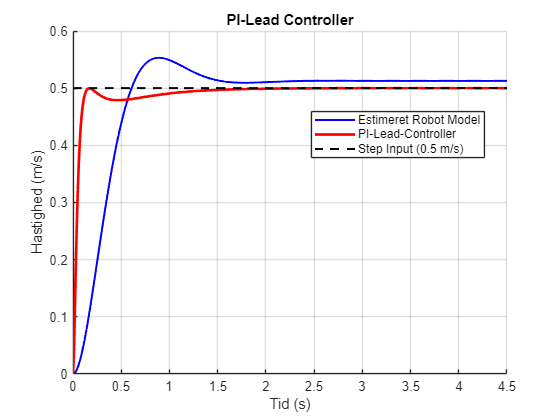


% Simulate step response for each system
[y_Gcl_PI_lead, t_Gcl] = step(0.5 * Gcl, t_sim);  % Closed-loop response

% Interpolate the closed-loop response to match measured time
y_Gcl_PI_Lead= interp1(t_Gcl, y_Gcl_PI_lead, time_trimmed, 'linear', 'extrap');

% Step Response Comparison
figure;
    hold on;
    
    % Plot all responses in one figure
    plot(time_trimmed, y_sys_tf_interp, 'b', 'LineWidth', 1.5); % Modeled system response
    plot(time_trimmed, y_Gcl_PI_Lead, 'r', 'LineWidth', 2); % Closed-loop response PI_Lead Forwarrd
    % Step input (black dashed)
    plot(time_trimmed, step_input, 'k--', 'LineWidth', 1.5);
    % Labels & legend
    title('PI-Lead Controller');
    xlabel('Tid (s)');
    ylabel('Hastighed (m/s)');
    xlim([0 4.5])
   legend('Estimeret Robot Model', 'PI-Lead-Controller','Step Input (0.5 m/s)' , 'Location', 'Best');
    grid on;
    hold off;


Gcl %displays the controller transfer function


Gcl =
 
                0.02152 s^6 + 2.554 s^5 + 31.07 s^4 + 174.7 s^3 + 510.7 s^2 + 597.8 s
  --------------------------------------------------------------------------------------------------
  9.813e-06 s^8 + 0.002187 s^7 + 0.1556 s^6 + 3.96 s^5 + 39.64 s^4 + 201.3 s^3 + 557.1 s^2 + 597.8 s
 
Continuous-time transfer function.


stepinfo(Gcl)

ans = struct with fields:
         RiseTime: 0.076737441875220
    TransientTime: 0.124547705663169
     SettlingTime: 0.124547705663169
      SettlingMin: 0.903845131504091
      SettlingMax: 0.999158903868133
        Overshoot: 0
       Undershoot: 0
             Peak: 0.999158903868133
         PeakTime: 0.169304782444129


ess = (1-dcgain(Gcl))

ess =      0


### Discritization.

T_s = 0.1; %Sample sending time

%Discrization using tustin method
%Implimentation:
Col_z = c2d(Col,T_s,'tustin');
Col_z = minreal(Col_z);
sys_z = c2d(sys_tf,T_s,'tustin')


sys_z =
 
  From input "u1" to output "y1":
  0.03947 + 0.07894 z^-1 + 0.03947 z^-2
  -------------------------------------
      1 - 1.419 z^-1 + 0.5732 z^-2
 
Sample time: 0.1 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 2
   Number of free coefficients: 5
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


Gcl_z = Col_z*sys_z/(1+Col_z*sys_z);
Gcl_z = minreal(Gcl_z);

Col_z


Col_z =
 
  23.05 z^2 - 32.01 z + 11.07
  ---------------------------
    z^2 - 0.3182 z - 0.6818
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties



p = pole(Col_z)

p =    1.000000000000000
  -0.681784107230939


z = zero(Col_z)

z =    0.737617683785618
   0.650980087888800


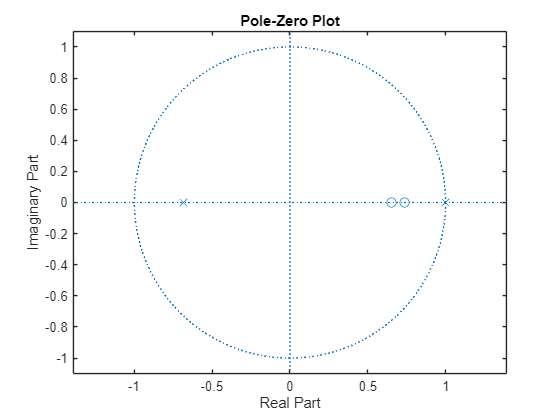

zplane(z, p);


[num_Col_z, den_Col_z] = tfdata(Col_z, 'v');
disp('Numerator Coefficients (b) (Controller Open loop):'), disp(num_Col_z);

Numerator Coefficients (b) (Controller Open loop):
  23.054783117344119 -32.013820463181034  11.070317218088730



disp('Denominator Coefficients (a) (Controller Open loop):'), disp(den_Col_z);

Denominator Coefficients (a) (Controller Open loop):
   1.000000000000000  -0.318215892769061  -0.681784107230939




Gcl_z


Gcl_z =
 
  0.4764 + 0.2913 z^-1 - 0.6179 z^-2 - 0.204 z^-3 + 0.2288 z^-4
  -------------------------------------------------------------
   1 - 0.6184 z^-1 - 0.4383 z^-2 + 0.2071 z^-3 + 0.02414 z^-4
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties

figure;
step(Gcl_z);
stepinfo(Gcl_z)

ans = struct with fields:
         RiseTime: 0.100000000000000
    TransientTime: 1.200000000000000
     SettlingTime: 1
      SettlingMin: 0.940759608538926
      SettlingMax: 1.062336391538128
        Overshoot: 6.233639153799331
       Undershoot: 0
             Peak: 1.062336391538128
         PeakTime: 0.100000000000000


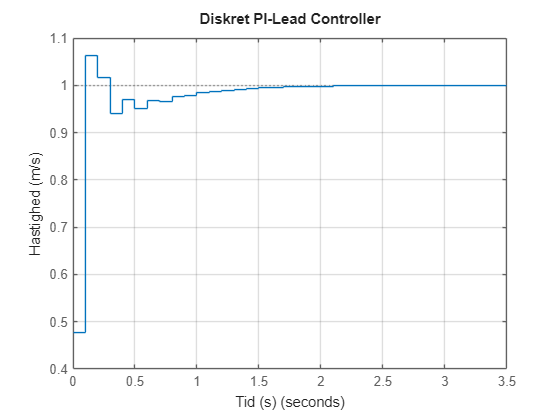

[num, den] = tfdata(Gcl_z, 'v');   % Extract vectors
xlabel('Tid (s)');
ylabel('Hastighed (m/s)');
title('Diskret PI-Lead Controller');
grid on;


zplane(num, den);                 % Plot manually
z = roots(num);   % Zeros = roots of numerator
p = roots(den);   % Poles = roots of denominator

disp('Zeros:'), disp(z)

Zeros:
 -1.000000000000000 + 0.000000007046324i
 -1.000000000000000 - 0.000000007046324i
  0.737617683785607 + 0.000000000000000i
  0.650980087888811 + 0.000000000000000i



disp('Poles:'), disp(p)

Poles:
  -0.593237006421222
   0.793575268129308
   0.517233364032171
  -0.099149663178527



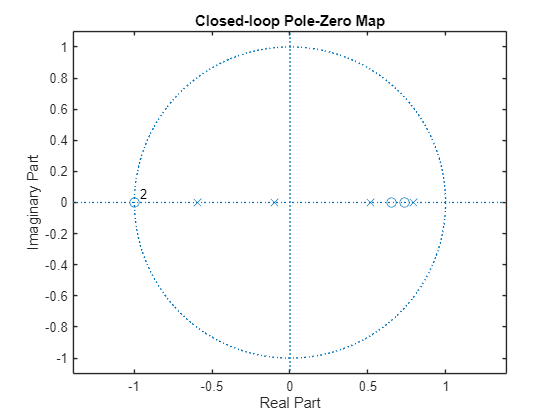

title('Closed-loop Pole-Zero Map');

ess =1 - dcgain(Gcl_z)

ess =     -1.270095140171179e-13



bodeplot(Gcl_z)
grid on,

### Final Implementation 

T_s = 0.1; %Sample sending time
num_C =  0.3*[23.054783117344119, -32.013820463181034, 11.070317218088730];
den_C = [1, 0.3*(-0.318215892769061), 0.3*(-0.681784107230939)];
Col_z_final = tf(num_C, den_C, T_s);

Gcl_z_final = Col_z_final*sys_z/(1+Col_z_final*sys_z)


Gcl_z_final =
 
  0.273 - 0.2466 z^-1 - 0.4692 z^-2 + 0.5679 z^-3 + 0.137 z^-4 - 0.3605 z^-5 + 0.08006 z^-6 + 0.04458 z^-7 - 0.01537 z^-8
  -----------------------------------------------------------------------------------------------------------------------
  1.273 - 3.276 z^-1 + 2.834 z^-2 - 0.4884 z^-3 - 0.557 z^-4 + 0.2323 z^-5 + 0.01733 z^-6 - 0.01065 z^-7 - 0.001622 z^-8
 
Sample time: 0.1 seconds
Discrete-time transfer function.


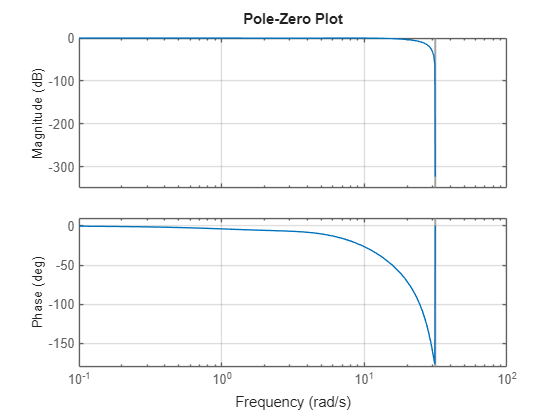



title('Pole-Zero Plot');

pole(Col_z_final)

ans =    0.502500030789590
  -0.407035262958871


zero(Col_z_final)

ans =    0.737617683785616
   0.650980087888802


[p,z] = pzmap(Gcl_z_final)

p =   0.709632219656033 + 0.263905502549626i
  0.709632219656033 - 0.263905502549626i
  0.665830973848937 + 0.119192184844628i
  0.665830973848937 - 0.119192184844628i
  0.502500030789579 + 0.000000000000000i
 -0.407035262958872 + 0.000000000000000i
 -0.136432049017707 + 0.071676192713138i
 -0.136432049017707 - 0.071676192713138i


z =  -1.000000015956098 + 0.000000000000000i
 -0.999999984043906 + 0.000000000000000i
 -0.407035262958872 + 0.000000000000000i
  0.709632219656023 + 0.263905502549624i
  0.709632219656023 - 0.263905502549624i
  0.737617683785586 + 0.000000000000000i
  0.650980087888844 + 0.000000000000000i
  0.502500030789582 + 0.000000000000000i


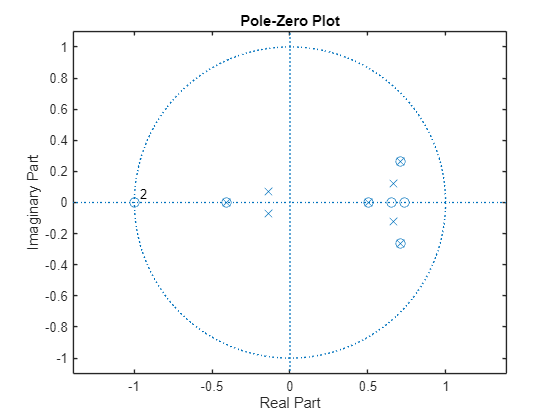


zplane(z, p);   % Plots poles (x) and zeros (o) on the z-plane

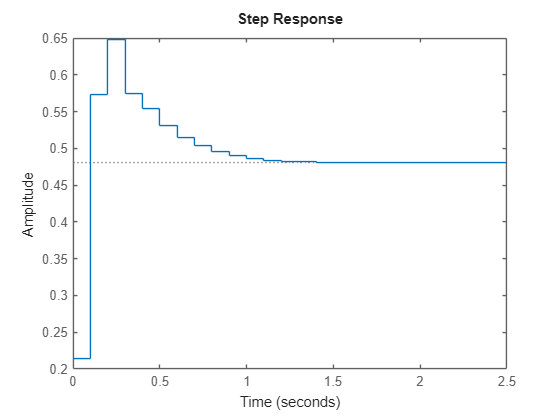

figure;
step(Gcl_z_final);

stepinfo(Gcl_z_final)

ans = struct with fields:
         RiseTime: 0.100000000000000
    TransientTime: 1
     SettlingTime: 0.900000000000000
      SettlingMin: 0.481069351177455
      SettlingMax: 0.648398337315190
        Overshoot: 34.722727316664773
       Undershoot: 0
             Peak: 0.648398337315190
         PeakTime: 0.200000000000000


Gcl_z_final


Gcl_z_final =
 
  0.273 - 0.2466 z^-1 - 0.4692 z^-2 + 0.5679 z^-3 + 0.137 z^-4 - 0.3605 z^-5 + 0.08006 z^-6 + 0.04458 z^-7 - 0.01537 z^-8
  -----------------------------------------------------------------------------------------------------------------------
  1.273 - 3.276 z^-1 + 2.834 z^-2 - 0.4884 z^-3 - 0.557 z^-4 + 0.2323 z^-5 + 0.01733 z^-6 - 0.01065 z^-7 - 0.001622 z^-8
 
Sample time: 0.1 seconds
Discrete-time transfer function.


ess =1- dcgain(Gcl_z_final)

ess =    0.518716440626135


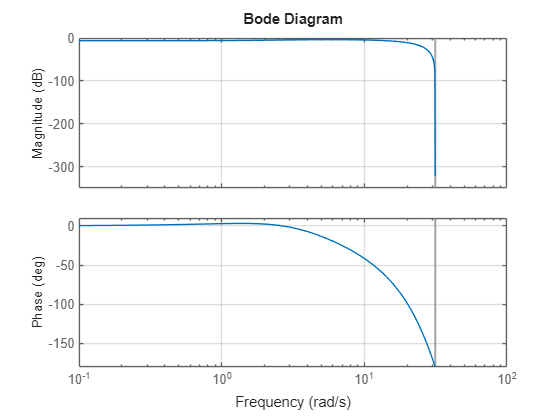


bodeplot(Gcl_z_final)
grid on,

Compare:

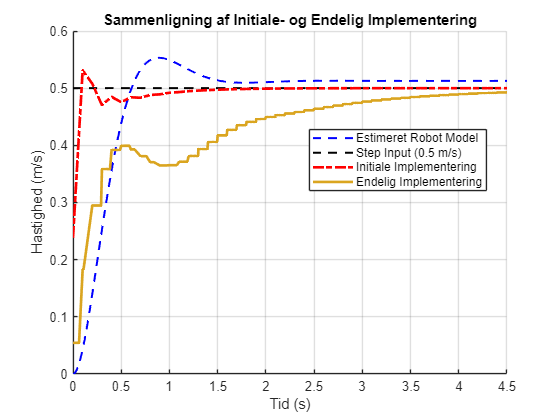

% Load step response from final implementation (.mat file)
step_data = load('Step_respons_modeling.mat');

% Plot everything in one figure
figure;
hold on;
% Modeled system response (blue dashed)
plot(time_trimmed, step_response_interp, 'b--', 'LineWidth', 1.5);
% Step input (black dashed)
plot(time_trimmed, step_input, 'k--', 'LineWidth', 1.5);
% Initial implementation (Gcl_z): faint gray dash-dot
[y_initial, t_initial] = step(0.5 * Gcl_z, time_trimmed(end));
plot(t_initial, y_initial, 'Color', 'r', 'LineWidth', 2, 'LineStyle', '-.');
% Final implementation from .mat file (red solid)
plot(step_data.data.Time, step_data.data.Data, 'Color', [218, 165, 32]/255, 'LineWidth', 2);
% Title and labels
title('Sammenligning af Initiale- og Endelig Implementering');
    xlabel('Tid (s)');
    ylabel('Hastighed (m/s)');
% Legend
   legend('Estimeret Robot Model', 'Step Input (0.5 m/s)' ,  'Initiale Implementering',  'Endelig Implementering','Location', 'Best');
xlim([0 4.5]);   %Limit time axis to 4.5 seconds
grid on;
hold off;



t_step = step_data.data.Time;
y_step = step_data.data.Data;

% Get step response characteristics
info = stepinfo(y_step, t_step);

% Display the results
disp(info);

         RiseTime: 1.899981666673895
    TransientTime: 3.699067404594104
     SettlingTime: 3.599251434694012
      SettlingMin: 0.445941272103661
      SettlingMax: 0.495441074566482
        Overshoot: 0
       Undershoot: 0
             Peak: 0.495441074566482
         PeakTime: 5




ess = 0.5 - info.SettlingMin   % Or SettlingMax

ess =    0.054058727896339
